# SectionC: LDA

## **Q1:**

**We want to see if we can discriminate two deformable and porous objects by touch: t****he black foam and the car sponge**

### **a: Use LDA to split the training data **

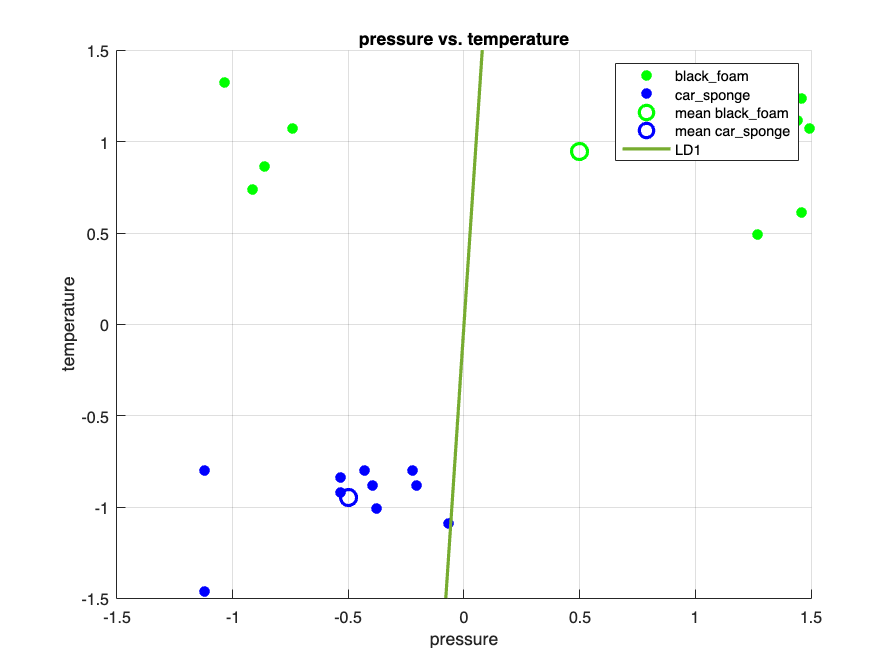

clear; clc;
% Import data: F1_PVT: 10x3x6
load('F1_PVT.mat');
str = ["acrylic","black_foam","car_sponge","flour_sack","kitchen_sponge","steel_vase"];
colors = ["r", "g", "b", "c", "m", "k"];

% --- set the classification dimentions and objects ---
% -----------------------------------------------------
obj_1 = "black_foam";
obj_2 = "car_sponge";
% -----------------------------------------------------

% initialize the index map, for automatic coloring and lableing
obj_map = dictionary(str,[1,2,3,4,5,6]);
dim_map = dictionary(["pressure","vibration","temperature"],[1,2,3]);
color_map = [colors(obj_map(obj_1)), colors(obj_map(obj_2))];


% --- Visualize results ---
%--------------pressure vs. temperature-------------------------
dim_1 = "pressure";
dim_2 = "temperature";
figure(1);
clf('reset');
hold on;
% plot the original data:
[extracted_data, mean_1, mean_2, theta] = LDA2D(obj_1, obj_2, dim_1, dim_2, F1_PVT, obj_map, dim_map);
plot(extracted_data(1:10,1),extracted_data(1:10,2), '.','color',color_map(1), 'MarkerSize',20);
plot(extracted_data(11:20,1), extracted_data(11:20,2),'.','color',color_map(2), 'MarkerSize',20);
plot(mean_1(1), mean_1(2), 'o', 'color',color_map(1), 'MarkerSize',10, 'LineWidth',2);
plot(mean_2(1), mean_2(2), 'o', 'color',color_map(2), 'MarkerSize',10,'LineWidth',2);

% plot the LDA line
% Linear Discriminant Analysis 
x = -1.5:0.1:1.5;
y = (theta(2)/theta(1))*x;
plot(x,y, 'LineWidth',2);
ylim([-1.5,1.5]);

grid on;
legend([obj_1, obj_2, "mean "+obj_1, "mean "+obj_2, "LD1"],'Interpreter', 'none');
xlabel(dim_1);
ylabel(dim_2);
title("pressure vs. temperature");
hold off;

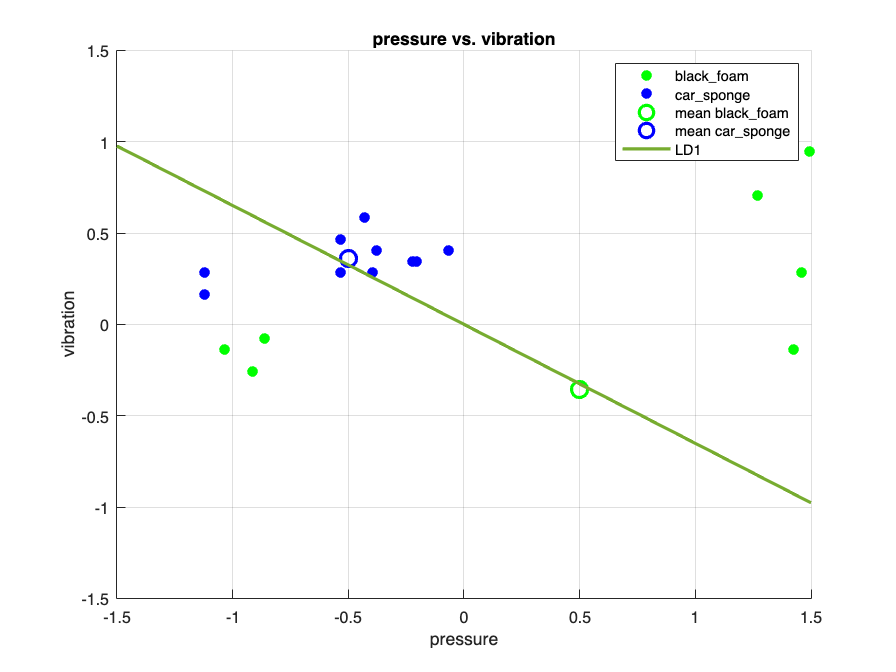


%------------------pressure vs. vibration--------------

dim_1 = "pressure";
dim_2 = "vibration";
figure(2);
clf('reset');
hold on;
% plot the original data:
[extracted_data, mean_1, mean_2, theta] = LDA2D(obj_1, obj_2, dim_1, dim_2, F1_PVT, obj_map, dim_map);
plot(extracted_data(1:10,1),extracted_data(1:10,2), '.','color',color_map(1), 'MarkerSize',20);
plot(extracted_data(11:20,1), extracted_data(11:20,2),'.','color',color_map(2), 'MarkerSize',20);
plot(mean_1(1), mean_1(2), 'o', 'color',color_map(1), 'MarkerSize',10, 'LineWidth',2);
plot(mean_2(1), mean_2(2), 'o', 'color',color_map(2), 'MarkerSize',10,'LineWidth',2);

% plot the LDA line
% Linear Discriminant Analysis 
x = -1.5:0.1:1.5;
y = (theta(2)/theta(1))*x;
plot(x,y, 'LineWidth',2);
ylim([-1.5,1.5]);
grid on;
legend([obj_1, obj_2, "mean "+obj_1, "mean "+obj_2, "LD1"],'Interpreter', 'none');
xlabel(dim_1);
ylabel(dim_2);
title("pressure vs. vibration")
hold off;

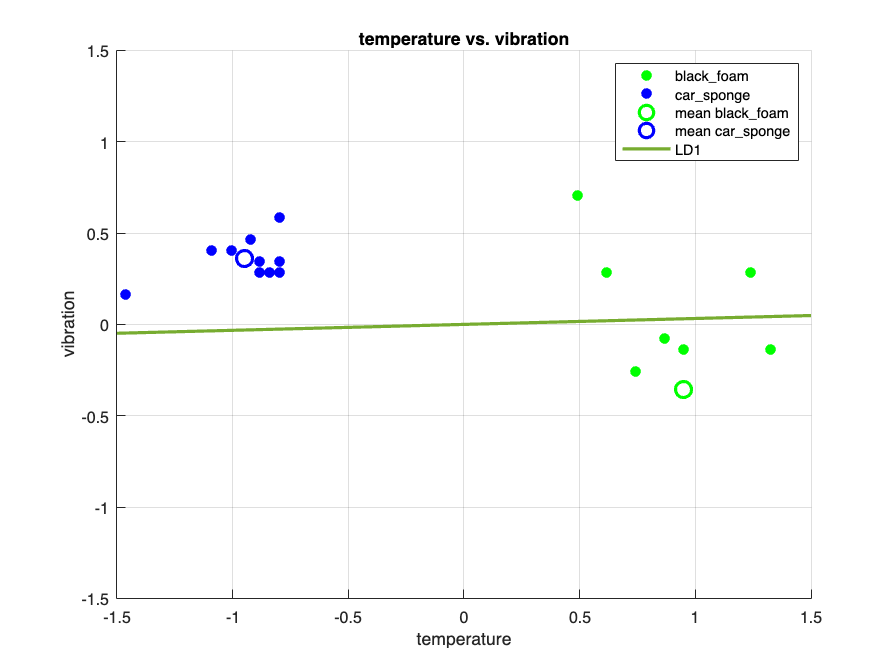



%-------------temperature vs. vibration--------------------------
dim_1 = "temperature";
dim_2 = "vibration";
figure(3);
clf('reset');
hold on;
% plot the original data:
[extracted_data, mean_1, mean_2, theta] = LDA2D(obj_1, obj_2, dim_1, dim_2, F1_PVT, obj_map, dim_map);
plot(extracted_data(1:10,1),extracted_data(1:10,2), '.','color',color_map(1), 'MarkerSize',20);
plot(extracted_data(11:20,1), extracted_data(11:20,2),'.','color',color_map(2), 'MarkerSize',20);
plot(mean_1(1), mean_1(2), 'o', 'color',color_map(1), 'MarkerSize',10, 'LineWidth',2);
plot(mean_2(1), mean_2(2), 'o', 'color',color_map(2), 'MarkerSize',10,'LineWidth',2);

% plot the LDA line
% Linear Discriminant Analysis 
x = -1.5:0.1:1.5;
y = (theta(2)/theta(1))*x;
plot(x,y, 'LineWidth',2);
ylim([-1.5,1.5]);
grid on;
legend([obj_1, obj_2, "mean "+obj_1, "mean "+obj_2, "LD1"],'Interpreter', 'none');
xlabel(dim_1);
ylabel(dim_2);
title("temperature vs. vibration");
hold off;

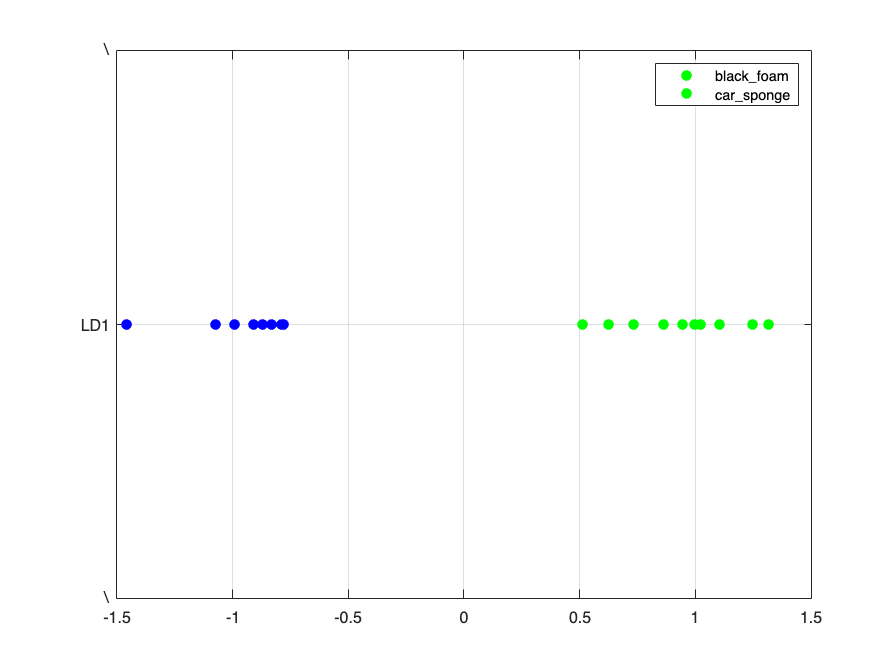

%--------------------------------------------------------



% plot the projections
figure(4);
clf('reset');
obj_1_data = extracted_data(1:10,:)*theta;
plot(obj_1_data, 0, '.','color',color_map(1),'MarkerSize',20);
hold on;
obj_2_data = extracted_data(11:20,:)*theta;
plot(obj_2_data, 0, '.','color',color_map(2),'MarkerSize',20);
ylim([-1,1]);
yticks([-1 0 1]);
legend([obj_1,obj_2],'Interpreter','none');
grid on;
set(gca,'yticklabel',{"\","LD1","\"});
hold off;

### **b:Now apply LDA to the three-dimensional PVT data.**

clear; clc;
% --- set the classification dimentions and objects ---
% -----------------------------------------------------
obj_1 = "flour_sack";
obj_2 = "steel_vase";
% -----------------------------------------------------

% Import data: F1_PVT: 10x3x6
load('F1_PVT.mat');
str = ["acrylic","black_foam","car_sponge","flour_sack","kitchen_sponge","steel_vase"];
colors = ["r", "g", "b", "c", "m", "k"];


% initialize the map between words and index
obj_map = dictionary(str,[1,2,3,4,5,6]);
dim_map = dictionary(["pressure","vibration","temperature"],[1,2,3]);
color_map = [colors(obj_map(obj_1)), colors(obj_map(obj_2))];

% LDA decompose
[extracted_data, LD1, LD2] = LDA3D(obj_1, obj_2, F1_PVT, obj_map);

eig_V =     0.9813    0.0091   -0.5252
   -0.1726   -0.8457   -0.8487
   -0.0854    0.5335   -0.0618


eig_D =     4.2855         0         0
         0   -0.0000         0
         0         0    0.0000



% --- Visualize result ---
figure(3);
clf('reset');

% plot the orginal data
plot3(extracted_data(1:10,1),extracted_data(1:10,2),extracted_data(1:10,3)...
    ,'.','color',color_map(1),'MarkerSize',20);
hold on;
plot3(extracted_data(11:20,1),extracted_data(11:20,2),extracted_data(11:20,3)...
    ,'.','color',color_map(2),'MarkerSize',20);

% plot the LD1 and LD2
% LD1
x_ld1 = -1.5:0.05:1.5;
y_ld1 = (LD1(2)/LD1(1))*x_ld1;
z_ld1 = (LD1(3)/LD1(1))*x_ld1;
plot3(x_ld1,y_ld1,z_ld1,'LineWidth',2)

% LD2
x_ld2 = -1.5:0.05:1.5;
y_ld2 = (LD2(2)/LD2(1))*x_ld2;
z_ld2 = (LD2(3)/LD2(1))*x_ld2;
plot3(x_ld2,y_ld2,z_ld2,'LineWidth',2)
xlim([-1,2]);
ylim([-4,2]);
zlim([-2,2]);
grid on;
legend([obj_1, obj_2, "LD1","LD2","LD Plane"],'Interpreter', 'none');



% 3D patch
"NOTE: (Incompletd display, BUG)open the figure in the seperate window to see the full plot"

ans = "NOTE: (Incompletd display, BUG)open the figure in the seperate window to see the full plot"

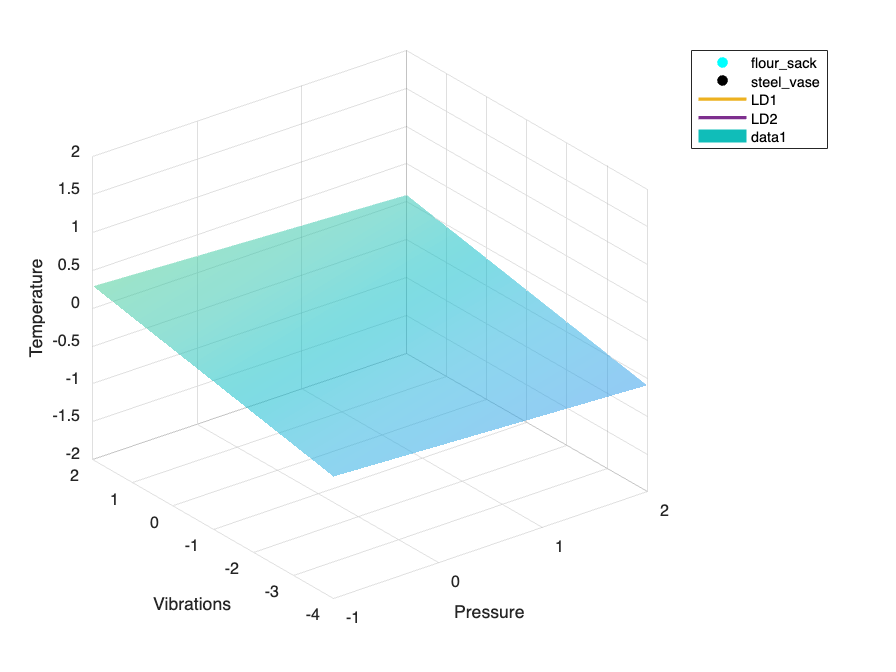

a = LD1.';
b = LD2.';
p = [0 0 0];
n = cross(a, b);
[X, Y] = meshgrid(-10:10, -10:10);
Z = -(n(1)*(X-p(1)) + n(2)*(Y-p(2))) / n(3) + p(3);
surf(X, Y, Z, 'facecolor','interp','FaceAlpha',0.5,'LineStyle','None');

xlabel('Pressure');
ylabel('Vibrations');
zlabel("Temperature");
hold off;

function [extracted_data, LD1, LD2] = LDA3D(obj_1, obj_2,  data, obj_map)
    % extract desired objects info from the complete 
    obj_index_1 = obj_map(obj_1);
    obj_index_2 = obj_map(obj_2);
    data = data(:,:,[obj_index_1, obj_index_2]);
    % reshape the data from tensor to matrix (10x2x2 -> 20x2)
    matrix = [];
    matrix = cat(1, matrix, data(:,:,1));
    data = cat(1, matrix, data(:,:,2));

    % Standerlize the data
    data = normalize(data,'zscore');

    % compute within class scatter matrix
    x_1 = data(1:10,:);
    x_2 = data(11:20,:);
    S_w = (x_1-mean(x_1)).'*(x_1-mean(x_1))...
        + (x_2-mean(x_2)).'*(x_2-mean(x_2));
   
    % compute between class scatter matrix
    S_b = (mean(x_1)-mean(x_2)).'*(mean(x_1)-mean(x_2));
    
    % combine scatter matrices
    S = S_w^-1*S_b;

    % eigen decomposition of scatter matrice
    [eig_V, eig_D] = eig(S)

    % Sort Eigenvalues
    [~, max_I] = maxk(diag(eig_D),2);
    
    % Create a Feature Vector
    LD1 = eig_V(:,max_I(1));
    LD2 = eig_V(:,max_I(2));
    extracted_data = data;
end

function [extracted_data, mean_1, mean_2, theta] = LDA2D(obj_1, obj_2, dim_1, dim_2, data, obj_map, dim_map)
    % extract desired objects info from the complete matrix
    obj_index_1 = obj_map(obj_1);
    obj_index_2 = obj_map(obj_2);
    dim_index_1 = dim_map(dim_1);
    dim_index_2 = dim_map(dim_2);
    data = data(:,[dim_index_1,dim_index_2],[obj_index_1, obj_index_2]);


    % reshape the data from tensor to matrix (10x2x2 -> 20x2)
    data = cat(1, data(:,:,1), data(:,:,2));

    % Standerlize the data
    data = normalize(data,'zscore');

    % compute within class scatter matrix
    x_1 = data(1:10,:);
    x_2 = data(11:20,:);
    S_w = (x_1-mean(x_1)).'*(x_1-mean(x_1))...
        + (x_2-mean(x_2)).'*(x_2-mean(x_2));
   
    % compute between class scatter matrix
    S_b = (mean(x_1)-mean(x_2)).'*(mean(x_1)-mean(x_2));
    
    % combine scatter matrices
    S = S_w^-1*S_b;

    % decompose the scatter matrice
    [eig_V, eig_D] = eig(S);

    % Sort Eigenvalues
    [~, max_I] = max(diag(eig_D));

    % Create a Feature Vector
    theta = eig_V(:,max_I);

    % return the calculation results
    extracted_data = data;
    mean_1 = mean(x_1);
    mean_2 = mean(x_2);
end

% line([0 0.9513],[1 0.3083+0.9513])
